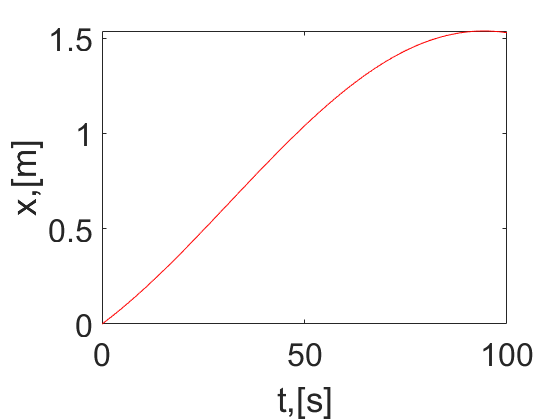

%% kinematic simulation land based mobile robot
clear all 
clc
close all 

%% simulation parameter

dt=0.1; % step size
ts=100; % simulation time
t=0:dt:ts; % time span

%% mobile robot parameter (Physical)

a = 0.05; % radius of the wheel(fixed)
d = 0.1; % distance between wheel frame to vehicle frame( along y-axis)


%% initial conditions
x0 = 0;
y0 = 0;
psi0=pi/4;

eta0 = [x0;y0;psi0];
eta(:,1)=eta0;

%% loop starts here
for i=1:length(t)
    psi = eta(3,i); % current orientation in rad
    %Jacobian matrix
    J_psi = [cos(psi),-sin(psi),0;
             sin(psi),cos(psi),0;
             0,0,1];
    %% inputs
    omega_1 = 0.5; % left wheel angular velocity
    omega_2 = 0.4; % right wheel angular velocity
    
    omega = [omega_1;omega_2];
    %% wheel configuration matrix 
    
    W =[a/2,a/2; 
        0,0;
        -a/(2*d), a/(2*d)];
    % velocity input commands
    zeta(:,i) = W*omega;
      
    % time derivative of generalized coordinates
    eta_dot(:,i) = J_psi * zeta(:,i);
    
    %% position propagation using Euler method
    eta(:,i+1) = eta(:,i) + dt * eta_dot(:,i); %state update
    % (generalized coordinates)
    
end

% plotting functions
figure
plot(t, eta(1, 1:i),'r');
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x,[m]');

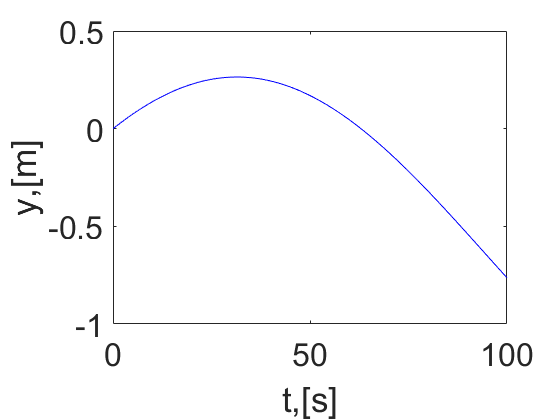

%
figure
plot(t, eta(2,1:i),'b-');
set(gca,'fontsize',24);
xlabel('t,[s]');
ylabel('y,[m]');

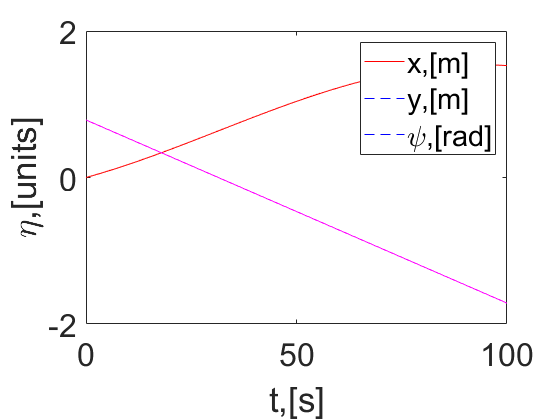

figure
plot(t, eta(1,1:i),'r');
hold on
plot(t, eta(2,i:i),'b--');
plot(t, eta(3,1:i),'m');
legend('x,[m]','y,[m]','\psi,[rad]');
set(gca,'fontsize',24)
xlabel('t,[s]');
ylabel('\eta,[units]');

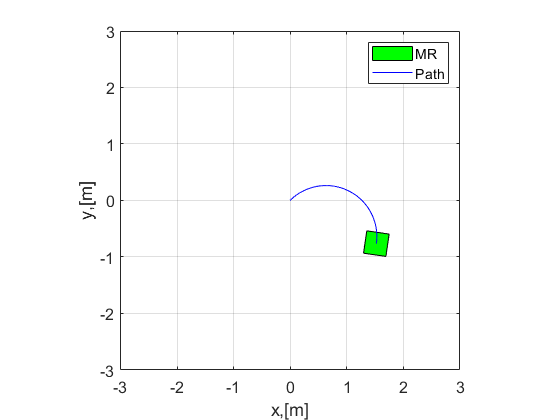


%% Animation (mobile robot motion animation)
l = 0.4; % length of the mobile robot
w = 0.4; % width of the mobile robot
% Mobile robot cooridinates
box_v = [-l/2,l/2,l/2,-l/2,-l/2;
         -w/2,-w/2,w/2,w/2,-w/2;];   
figure
for i = 1:5:length(t)
    psi = eta(3,i);
    R_psi = [cos(psi), -sin(psi);
             sin(psi), cos(psi);]; % rotation matrix
    v_pos = R_psi*box_v;
    fill(v_pos(1, :)+eta(1,i),v_pos(2,:)+eta(2,i),'g')
    hold on, grid on
    axis([-3 3 -3 3]), axis square
    plot(eta(1,1:i),eta(2,1:i),'b-');
    legend('MR','Path')
    set(gca, 'fontsize',12)
    xlabel('x,[m]'); ylabel('y,[m]');
    pause(0.01)
    hold off
end % animation ends here